# Exploring the Experiment's Design

In this set of exercises, we'll get our first look at the experiment we'll be analyzing in this course; curated data from the [Steinmetz et al, 2019](https://www.nature.com/articles/s41586-019-1787-x) paper.

Today's data is focused on three CSV files, each containing sessions  from a different stretch of data collection.  They contain trial-level  data from the experiment:

- steinmetz_winter2016.csv

- steinmetz_summer2017.csv

- steinmetz_winter2017.csv

## Loading and viewing data

Let's load in some csv data with MATLAB and see what we have!

**Download datafiles**

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "src"))
download_from_sciebo("https://uni-bonn.sciebo.de/s/QyHoxfrSF6JILQd", 'data/steinmetz_winter2016.csv')

downloading file to data/steinmetz_winter2016.csv
Done!

download_from_sciebo("https://uni-bonn.sciebo.de/s/Z3QHxJztEueDQF8", 'data/steinmetz_summer2017.csv')

downloading file to data/steinmetz_summer2017.csv
Done!

download_from_sciebo("https://uni-bonn.sciebo.de/s/9FxelLhARmHpw85", 'data/steinmetz_winter2017.csv')

downloading file to data/steinmetz_winter2017.csv
Done!

userpath(fullfile(fileparts(matlab.desktop.editor.getActiveFilename), "data"))


**Example: **

Load in the winter 2016 dataset and view the first 5 rows of the data

data_winter2016 = readtable('data/steinmetz_winter2016.csv');
data_winter2016(1:5,:)

ans = 5×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type     mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    ________    ____________    __________

    

The variable data is a MATLAB table, we can see that in the Workspace pannel on the right.

**Exercises**

Load in the summer 2017 dataset and view the first 10 rows of the data

data_summer2017 = readtable('data/steinmetz_summer2017.csv');
data_summer2017(1:10,:)

ans = 10×15 table
    trial    active_trials    contrast_left    contrast_right    stim_onset    gocue_time    response_type    response_time    feedback_time    feedback_type    reaction_time    reaction_type      mouse      session_date    session_id
    _____    _____________    _____________    ______________    __________    __________    _____________    _____________    _____________    _____________    _____________    _____________    _________    ____________    __________

 

How many rows are in the summer 2017 dataset?

height(data_summer2017)

ans = 2747

How many columns are in the summer 2017 dataset?

width(data_summer2017)

ans = 15

What are the column names in the summer 2017 dataset?

data_summer2017.Properties.VariableNames

ans = 1×15 cell array
    {'trial'}    {'active_trials'}    {'contrast_left'}    {'contrast_right'}    {'stim_onset'}    {'gocue_time'}    {'response_type'}    {'response_time'}    {'feedback_time'}    {'feedback_type'}    {'reaction_time'}    {'reaction_type'}    {'mouse'}    {'session_date'}    {'session_id'}


Load in the winter 2017 dataset to an appropriately named variable

data_winter2017 = readtable('data/steinmetz_winter2017.csv');

Combine the 3 datasets into one table named `data`

data = [data_winter2016; data_winter2017; data_summer2017];

How many trials are there in the combined dataset?

height(data)

ans = 14420

Are you sure that the combined dataset has all the rows of the 3 smaller datasets? 

Count the rows in each to find out.

height(data_winter2017)+ height(data_summer2017)+ height(data_winter2016) == height(data)

ans = logical
   1


## Experiment Description: Calculating Statistics on Continuous Data

Let's calculate some simple statistics from the dataset.

**Example**

Find the minimum response time in the data

min(data.response_time)

ans = 0.4794

**Exercises**

Find the maximum response time in the data

max(data.response_time)

ans = 2.7136

Find the maximum gocue time in the data

max(data.gocue_time)

ans = 1.1988

Find the minimum gocue time in the data

min(data.gocue_time)

ans = 0.3951

Find the mean response time in the data. Hint - as the data contains missing values use the "omitmissing" option.

mean(data.response_time,"omitmissing")

ans = 1.4228

Calculate the mean of response time including missing values. How do missing values affect the result?

mean(data.response_time)

ans = NaN

Find the median response_time in the data

median(data.response_time,"omitmissing")

ans = 1.1833

Find the standard deviation of response time

std(data.response_time,"omitmissing")

ans = 0.6614

Find the standard deviation of gocue time

std(data.gocue_time,"omitmissing")

ans = 0.2005

Find the range of gocue time 

range(data.gocue_time)

ans = 0.8038

Find the range of feedback time using the `max()` and `min()` functions

max(data.feedback_time) - min(data.feedback_time)

ans = 2.2438

## Experiment Description: Calculating Statistics of Across Categorical Data

In data  science we often want to perform analysis on distinct separate categories, for example, analysing trials that occured on different days. 

To do this, we group the data and analyse each group separately.

**Example Exercise**

How many trials occurred for each session date?

groupsummary(data,"session_date")

ans = 31×2 table
    session_date    GroupCount
    ____________    __________

    14-Dec-2016        364    
    17-Dec-2016        401    
    18-Dec-2016        378    
    07-Jan-2017        554    
    08-Jan-2017        632    
    09-Jan-2017        585    
    10-Jan-2017        363    
    11-Jan-2017        252    
    12-Jan-2017        238    
    15-May-2017        357    
    16-May-2017        345    
    18-May-2017        194    
    15-Jun-2017        360    
    16-Jun-2017        482    
    17-Jun-2017        557    
    18-Jun-2017        452    


**Exercises**

How many trials did each mouse participate in?

groupsummary(data,"mouse")

ans = 10×2 table
        mouse        GroupCount
    _____________    __________

    {'Cori'     }       1143   
    {'Forssmann'}       1485   
    {'Hench'    }       1851   
    {'Lederberg'}       2902   
    {'Moniz'    }        896   
    {'Muller'   }       1112   
    {'Radnitz'  }       1512   
    {'Richards' }       1677   
    {'Tatum'    }       1389   
    {'Theiler'  }        453   


What was the mean response time for each mouse?

groupsummary(data,"mouse", "mean", "response_time")

ans = 10×3 table
        mouse        GroupCount    mean_response_time
    _____________    __________    __________________

    {'Cori'     }       1143             1.5909      
    {'Forssmann'}       1485             1.4706      
    {'Hench'    }       1851             1.5257      
    {'Lederberg'}       2902             1.1438      
    {'Moniz'    }        896             1.7777      
    {'Muller'   }       1112             1.5758      
    {'Radnitz'  }       1512             1.5591      
    {'Richards' }       1677             1.3583      
    {'Tatum'    }       1389             1.3377      
    {'Theiler'  }        453             1.3388      


What was the minimum response time for each mouse?

groupsummary(data,"mouse", "min", "response_time")

ans = 10×3 table
        mouse        GroupCount    min_response_time
    _____________    __________    _________________

    {'Cori'     }       1143            0.56821     
    {'Forssmann'}       1485            0.49491     
    {'Hench'    }       1851            0.55218     
    {'Lederberg'}       2902            0.47941     
    {'Moniz'    }        896            0.68261     
    {'Muller'   }       1112             0.5854     
    {'Radnitz'  }       1512            0.58381     
    {'Richards' }       1677            0.50589     
    {'Tatum'    }       1389            0.51359     
    {'Theiler'  }        453            0.48259     


What was the most common (ie. mode) reaction_type for each mouse?

groupsummary(data,"mouse", "mode", "reaction_type")

ans = 10×3 table
        mouse        GroupCount    mode_reaction_type
    _____________    __________    __________________

    {'Cori'     }       1143                1        
    {'Forssmann'}       1485               -1        
    {'Hench'    }       1851                1        
    {'Lederberg'}       2902               -1        
    {'Moniz'    }        896               -1        
    {'Muller'   }       1112                1        
    {'Radnitz'  }       1512               -1        
    {'Richards' }       1677                0        
    {'Tatum'    }       1389                1        
    {'Theiler'  }        453               -1        


What was the range of response times for each session date?

groupsummary(data,"session_date", "range", "response_time")

ans = 31×3 table
    session_date    GroupCount    range_response_time
    ____________    __________    ___________________

    14-Dec-2016        364              2.1054       
    17-Dec-2016        401              2.1227       
    18-Dec-2016        378              2.1076       
    07-Jan-2017        554              2.1245       
    08-Jan-2017        632              2.1158       
    09-Jan-2017        585              2.0917       
    10-Jan-2017        363              2.0796       
    11-Jan-2017        252              2.0306       
    12-Jan-2017        238              1.9787       
    15-May-2017        357              1.9979       
    16-May-2017        345              1.9422       
    18-May-2017        194              2.0036       
    15-Jun-2017        360              2.1031       
    16-Jun-2017        482              2.1031       
    17-Jun-2017 

Rerun the last exercise replaceing "range" with "all"

groupsummary(data,"session_date", "all", "response_time")

ans = 31×14 table
    session_date    GroupCount    mean_response_time    sum_response_time    min_response_time    max_response_time    range_response_time    median_response_time    mode_response_time    var_response_time    std_response_time    nummissing_response_time    nnz_response_time    numunique_response_time
    ____________    __________    __________________    _________________    _________________    _________________    ___________________    ____________________    __________________    _________________    _________________    ________________

What was the largest number of trials that any mouse took part in? **Hint **- the `groupsummary` function returns a table, from which you can perform compuations on 

mouse_trial_count = groupsummary(data,"mouse");
max(mouse_trial_count.GroupCount)

ans = 2902

How many trials did each mouse take part in on each session date?

groupsummary(data,["mouse","session_date"])

ans = 39×3 table
        mouse        session_date    GroupCount
    _____________    ____________    __________

    {'Cori'     }    14-Dec-2016        364    
    {'Cori'     }    17-Dec-2016        401    
    {'Cori'     }    18-Dec-2016        378    
    {'Forssmann'}    01-Nov-2017        359    
    {'Forssmann'}    02-Nov-2017        364    
    {'Forssmann'}    04-Nov-2017        400    
    {'Forssmann'}    05-Nov-2017        362    
    {'Hench'    }    15-Jun-2017        360    
    {'Hench'    }    16-Jun-2017        482    
    {'Hench'    }    17-Jun-2017        557    
    {'Hench'    }    18-Jun-2017        452    
    {'Lederberg'}    05-Dec-2017        450    
    {'Lederberg'}    06-Dec-2017        410    
    {'Lederberg'}    07-Dec-2017        378    
    {'Lederberg'}    08-Dec-2017        514    
    {'Lederberg'}    09-Dec-2017        390    


What was the average number of trials that each mouse participated in in a session? 

mouse_session_count = groupsummary(data,["mouse","session_date"]);
mean(mouse_session_count.GroupCount)

ans = 369.7436

## Visualizing the Experimental Design using Plots

**Example Exercise**

Make a bar plot showing how many times each response type appeared in the data

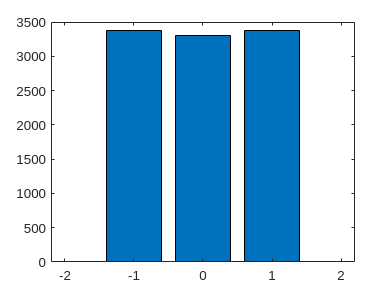

response_type_count = groupsummary(data, "response_type");
bar(response_type_count.response_type, response_type_count.GroupCount)

**Exercises**

Plot the counts of feedback type from the dataset as a bar plot

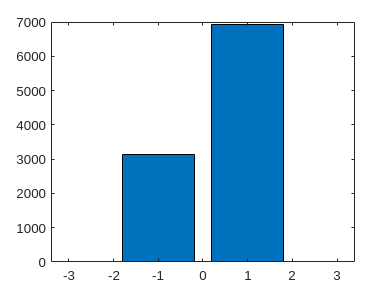

response_type_count = groupsummary(data, "feedback_type");
bar(response_type_count.feedback_type, response_type_count.GroupCount)

Make a bar plot showing the frequency of each `contrast_left` value with red bars

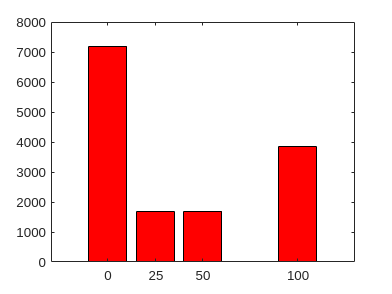

contrast_left_count = groupsummary(data, "contrast_left");
bar(contrast_left_count.contrast_left, contrast_left_count.GroupCount, 'red')

Make a bar plot showing how many trials each mouse participated in

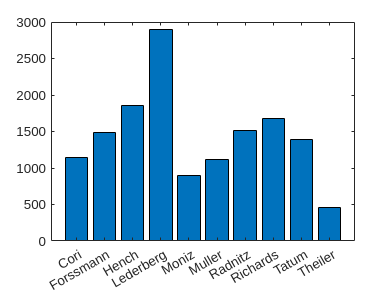

trials_by_mouse = groupsummary(data, "mouse");
bar(trials_by_mouse.mouse, trials_by_mouse.GroupCount)

Recreate the above bar plot, but sorting the bars from smallest to largest. 

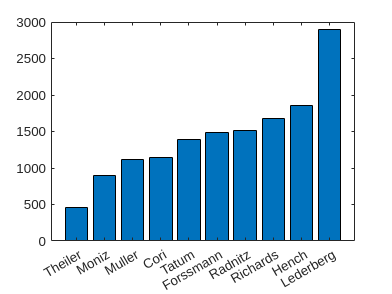

trials_by_mouse = groupsummary(data, "mouse");
trials_by_mouse = sortrows(trials_by_mouse, "GroupCount");

bar(trials_by_mouse.mouse, trials_by_mouse.GroupCount)

Add an appropriate y label to your plot

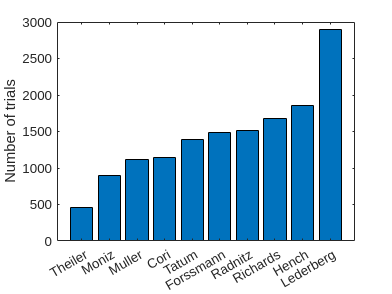

trials_by_mouse = groupsummary(data, "mouse");
trials_by_mouse = sortrows(trials_by_mouse, "GroupCount");

bar(trials_by_mouse.mouse, trials_by_mouse.GroupCount)
ylabel('Number of trials')

Make a pie chart showing the percentage of trials that each mouse participated in. **Hint** - the input to piechart must be categorical data. 

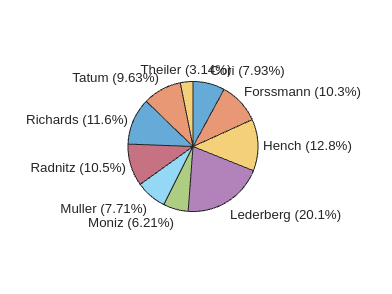

mice = categorical(data.mouse);
piechart(mice)

Make a swarmchart showing the response time distributions for each mouse. **Hint** - the x data inputted to swarmchart must be categorical data 

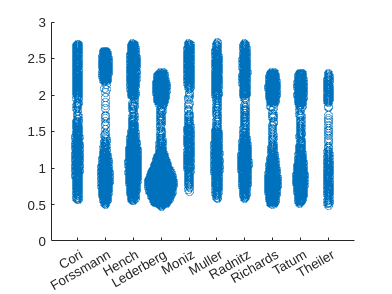

ans = 31×1 datetime array
   14-Dec-2016
   17-Dec-2016
   18-Dec-2016
   07-Jan-2017
   08-Jan-2017
   09-Jan-2017
   10-Jan-2017
   11-Jan-2017
   12-Jan-2017
   15-May-2017
   16-May-2017
   18-May-2017
   15-Jun-2017
   16-Jun-2017
   17-Jun-2017
   18-Jun-2017
   11-Oct-2017
   29-Oct-2017
   30-Oct-2017
   31-Oct-2017
   01-Nov-2017
   02-Nov-2017
   04-Nov-2017
   05-Nov-2017
   05-Dec-2017
   06-Dec-2017
   07-Dec-2017
   08-Dec-2017
   09-Dec-2017
   10-Dec-2017


trials_by_date = 31×3 table
    day_session_date    GroupCount    Percent
    ________________    __________    _______

      14-Dec-2016          364        2.5243 
      17-Dec-2016          401        2.7809 
      18-Dec-2016          378        2.6214 
      07-Jan-2017          554        3.8419 
      08-Jan-2017          632        4.3828 
      09-Jan-2017          585        4.0569 
      10-Jan-2017          363        2.5173 
      11-Jan-2017          252        1.7476 
      12-Jan-2017          238        1.6505 
      15-May-2017          357        2.4757 
      16-May-2017          345        2.3925 
      18-May-2017          194        1.3454 
      15-Jun-2017          360        2.4965 
      16-Jun-2017          482        3.3426 
      17-Jun-2017          557        3.8627 
      18-Jun-2017          452        3.1345 


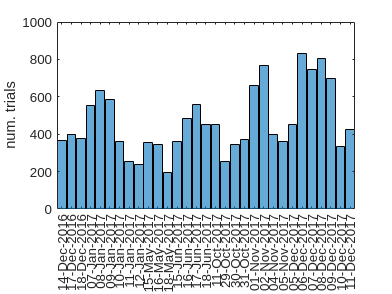

trials_by_date = 31×2 table
    session_date    GroupCount
    ____________    __________

    14-Dec-2016        364    
    17-Dec-2016        401    
    18-Dec-2016        378    
    07-Jan-2017        554    
    08-Jan-2017        632    
    09-Jan-2017        585    
    10-Jan-2017        363    
    11-Jan-2017        252    
    12-Jan-2017        238    
    15-May-2017        357    
    16-May-2017        345    
    18-May-2017        194    
    15-Jun-2017        360    
    16-Jun-2017        482    
    17-Jun-2017        557    
    18-Jun-2017        452    


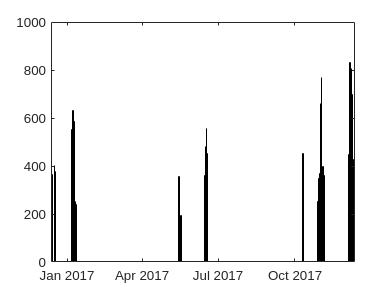

swarmchart(categorical(data.mouse), data.response_time)

## Demonstration: 3D bar plot

Here is an example showing how the` groupcounts `function can be used to make a 3D bar plot showing how many trials each mouse underwent on each session date.

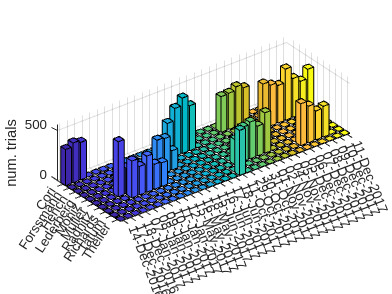

[B,BG,BP]=groupcounts({data.mouse, data.session_date}, "IncludeEmptyGroups",true);
session_dates = unique(data.session_date); 
mouse_names = unique(data.mouse);
bar3(reshape(B,length(session_dates),length(mouse_names))')
yticklabels(mouse_names)
xticks([1:1: length(session_dates)])
xticklabels( datestr(session_dates))

zlabel('num. trials')